Step 1: Load Dataset

data = readtable("C:\Users\yashw_d6scpoj\Desktop\S2\MFC2\smoted_dataset1.csv");

Step 2: Remove Non-Numeric Features (src_ip, dst_ip)

data(:, {'src_ip', 'dst_ip'}) = []; % Remove categorical columns

Step 3: Extract Features and Target Variable

X = table2array(data(:, 1:end-1)); % Convert numeric features to matrix
Y = table2array(data(:, end)); % Convert labels to numeric array

%Convert categorical labels to numerical if needed
Y = grp2idx(Y);

Split data into training (80%) and testing (20%)

cv = cvpartition(Y, 'HoldOut', 0.2);
X_train = X(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X(test(cv), :);
Y_test = Y(test(cv), :);

Training and Prediction

%Train Decision Tree (CART) model
CART_model = fitctree(X_train, Y_train);

%Predict on test data
CART_pred = predict(CART_model, X_test);

Evaluation

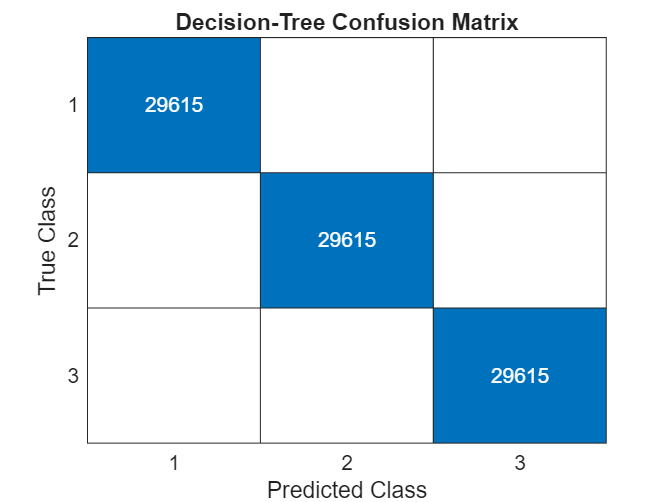

%Confusion Matrix
figure;
confusionchart(Y_test, CART_pred);
title('Decision-Tree Confusion Matrix');



%Calculate Accuracy
CART_accuracy = sum(CART_pred == Y_test) / length(Y_test) * 100;
disp(['Accuracy: ', num2str(CART_accuracy), '%'])

Accuracy: 100%
